# Summary of Identification Methods

## Daten laden

Der nachfolgende Code lädt die Daten aus der Datei 'data.xlsx' und speichert sie in entsprechenden Variablen. Der Datensatz enthält monatliche Daten zu Zinsen (federal funds rate) und Aktienkursen (S&P 500).

% Lade Daten
load("data.mat")
year = data(:,1);
month = data(:,2);
date = year + (month-1) / 12;
i	= data(:,3); % Interest Rate
sp500= data(:,4); % S&P 500

DSP500 = dlog(sp500, 1); 
date_p = date(2:end);
Y = [ i,DSP500];  Y=Y(2:end,:);
Y_names = {"i" "DSP500"  };

p = 4;
[a, u, Y_hat]  =  VAR(Y,p);

--------------------------------------------------------------
                              OLS                            
--------------------------------------------------------------
N  = 379                                   R^2  =       0.9951
DF = 370                                   RBar =       0.9950
                                           F    =    9381.1559
                                           p(F) =       0.0000
 
variable           coef           se            t            p
       1         0.0087       0.0171       0.5070       0.6124
       2         1.4873       0.0512      29.0707       0.0000
       3         0.6371       0.2256       2.8244       0.0050
       4        -0.6630       0.0907      -7.3092       0.0000
       5         0.4575       0.2281       2.0052       0.0457
       6         0.3282       0.0880       3.7284       0.0002
       7         0.2183       0.2290       0.9532       0.3411
       8        -0.1597       0.0486      -3.2876     

u = u(p+1:end,:); 
A = get_A(a);
phi = get_phi(A, 12*2);   

date_p = date_p(p+1:end);



Plotte 100 mögliche Impulsantworten mit unkorrelierten Schocks

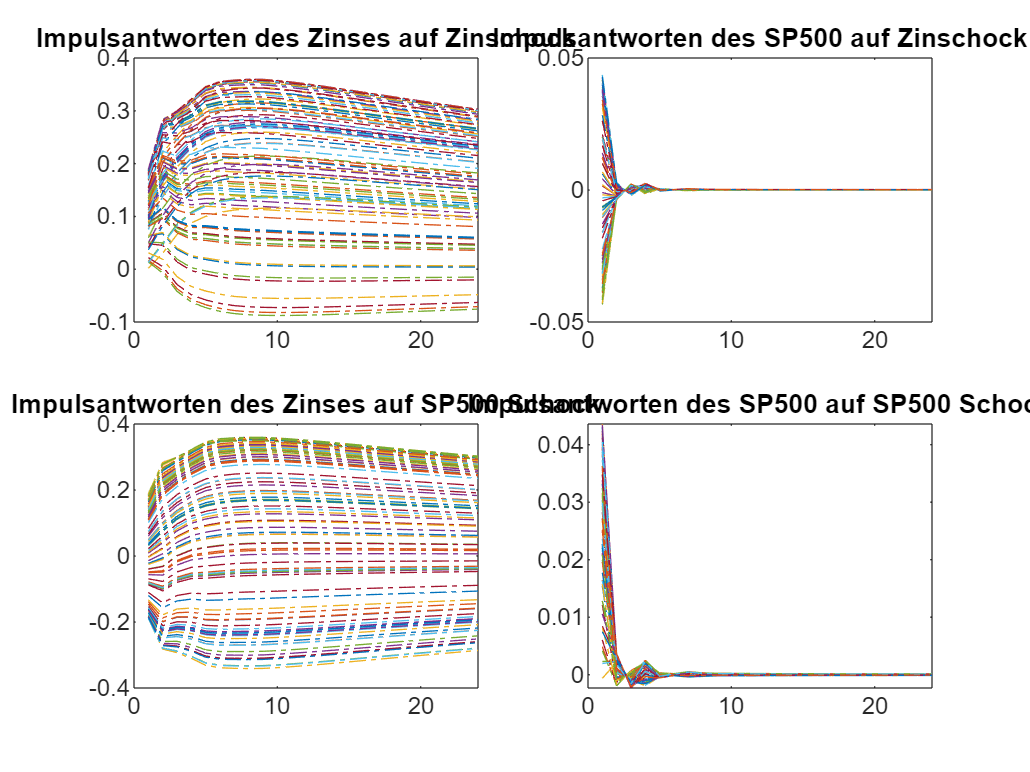


[~, Bchol] = recursive_SVAR(u);  

psi_ResponseSP500_ShockI = NaN(12*2,100);
psi_ResponseI_SchockI = NaN(12*2,100);
psi_ResponseSP500_ShockSP500 = NaN(12*2,100);
psi_ResponseI_SchockSP500 = NaN(12*2,100);

O_all = NaN(2,2,100);
for i = 1:100
   O = generateRandomOrthogonalMatrix(2);
   O_all(:,:,i) = O;
end

for i = 1:100
 O = O_all(:,:,i) ;
    psi_tmp = get_psi(phi,Bchol*O); 


    psi_ResponseSP500_ShockI(:,i) = squeeze(psi_tmp(2,1,:));
    psi_ResponseI_SchockI(:,i) = squeeze(psi_tmp(1,1,:));

    psi_ResponseSP500_ShockSP500(:,i) = squeeze(psi_tmp(2,2,:));
    psi_ResponseI_SchockSP500(:,i) = squeeze(psi_tmp(1,2,:));
end

figure
subplot(2,2,1)
plot(psi_ResponseI_SchockI,LineStyle="-.") 
title("Impulsantworten des Zinses auf Zinschock")
subplot(2,2,2)
plot(psi_ResponseSP500_ShockI,LineStyle="-.")  
title("Impulsantworten des SP500 auf Zinschock")
subplot(2,2,3)
plot(psi_ResponseI_SchockSP500,LineStyle="-.") 
title("Impulsantworten des Zinses auf SP500 Schock")
subplot(2,2,4)
plot(psi_ResponseSP500_ShockSP500,LineStyle="-.")  
title("Impulsantworten des SP500 auf SP500 Schock") 

Rekursives SVAR in Zins und SP500: Restringiert die simultane Antwort des Zinses auf einen SP500 Schock auf Null.

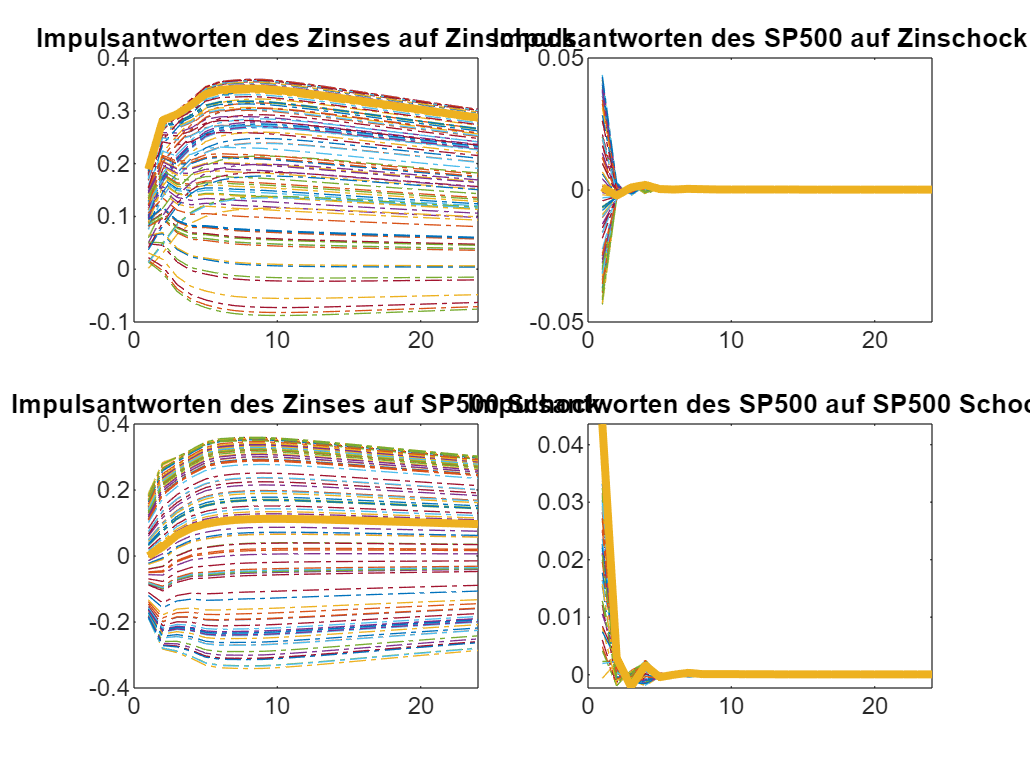


psi_recursive = get_psi(phi,Bchol); 

psi_recursive_ResponseSP500_ShockI = squeeze(psi_recursive(2,1,:));
psi_recursive_ResponseI_SchockI = squeeze(psi_recursive(1,1,:));

psi_recursive_ResponseSP500_ShockSP500 = squeeze(psi_recursive(2,2,:));
psi_recursive_ResponseI_SchockSP500 = squeeze(psi_recursive(1,2,:));

figure
subplot(2,2,1)
plot(psi_ResponseI_SchockI,LineStyle="-." )   
hold on
plot(psi_recursive_ResponseI_SchockI, LineWidth=3)  
title("Impulsantworten des Zinses auf Zinschock")
subplot(2,2,2)
plot(psi_ResponseSP500_ShockI,LineStyle="-.")  
hold on
plot(psi_recursive_ResponseSP500_ShockI, LineWidth=3)  
title("Impulsantworten des SP500 auf Zinschock")
subplot(2,2,3)
plot(psi_ResponseI_SchockSP500,LineStyle="-.")   
hold on
plot(psi_recursive_ResponseI_SchockSP500, LineWidth=3)  
title("Impulsantworten des Zinses auf SP500 Schock")
subplot(2,2,4)
plot(psi_ResponseSP500_ShockSP500,LineStyle="-.")  
hold on
plot(psi_recursive_ResponseSP500_ShockSP500, LineWidth=3)  
title("Impulsantworten des SP500 auf SP500 Schock") 

Vorzeichenrestriktionen: Restringiert die möglichen Impulsantworten auf die mit einer negativen Antwort des SP500 auf Zinsschocks.

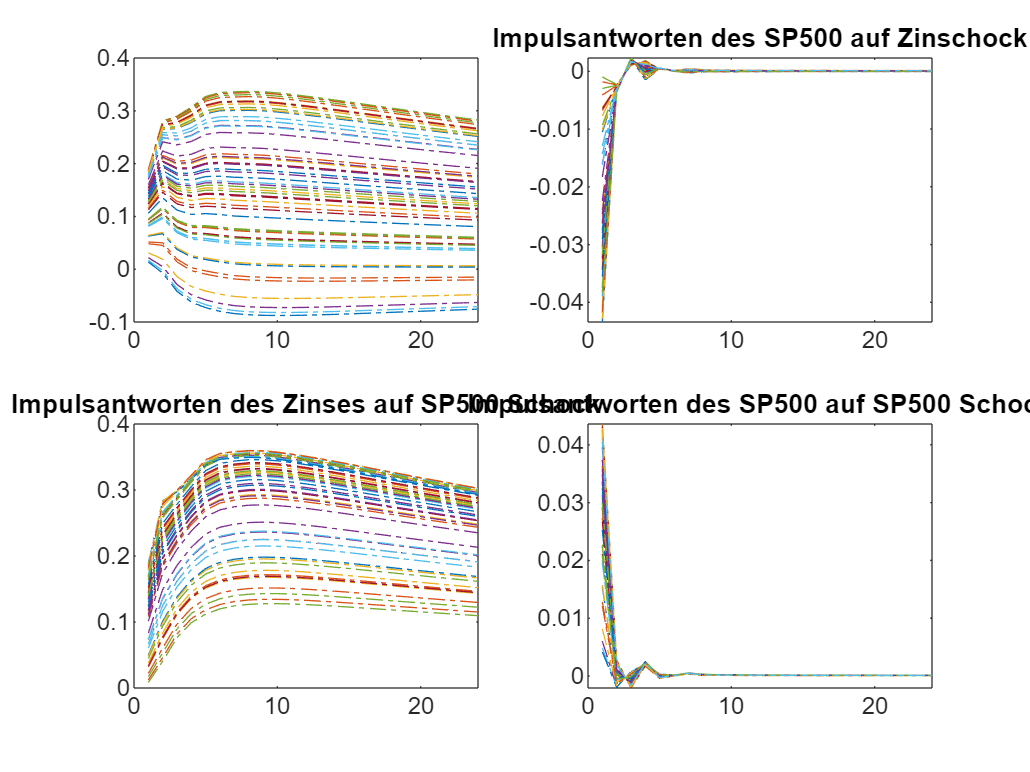

select = ones(100,1);
for i = 1:100
    if psi_ResponseSP500_ShockI(1,i)>0
        select(i) = 0;
    end
end

figure
subplot(2,2,1)
plot(psi_ResponseI_SchockI(:,select==1),LineStyle="-.")    
subplot(2,2,2)
plot(psi_ResponseSP500_ShockI(:,select==1),LineStyle="-.")   
title("Impulsantworten des SP500 auf Zinschock")
subplot(2,2,3)
plot(psi_ResponseI_SchockSP500(:,select==1),LineStyle="-.")    
title("Impulsantworten des Zinses auf SP500 Schock")
subplot(2,2,4)
plot(psi_ResponseSP500_ShockSP500(:,select==1),LineStyle="-.")   
title("Impulsantworten des SP500 auf SP500 Schock") 

Narrative Vorzeichenrestriktionen: Restringiert das Vorzeichen oder eine andere Eigenschaft des Schocks an einem bestimmten Zeitpunkt.

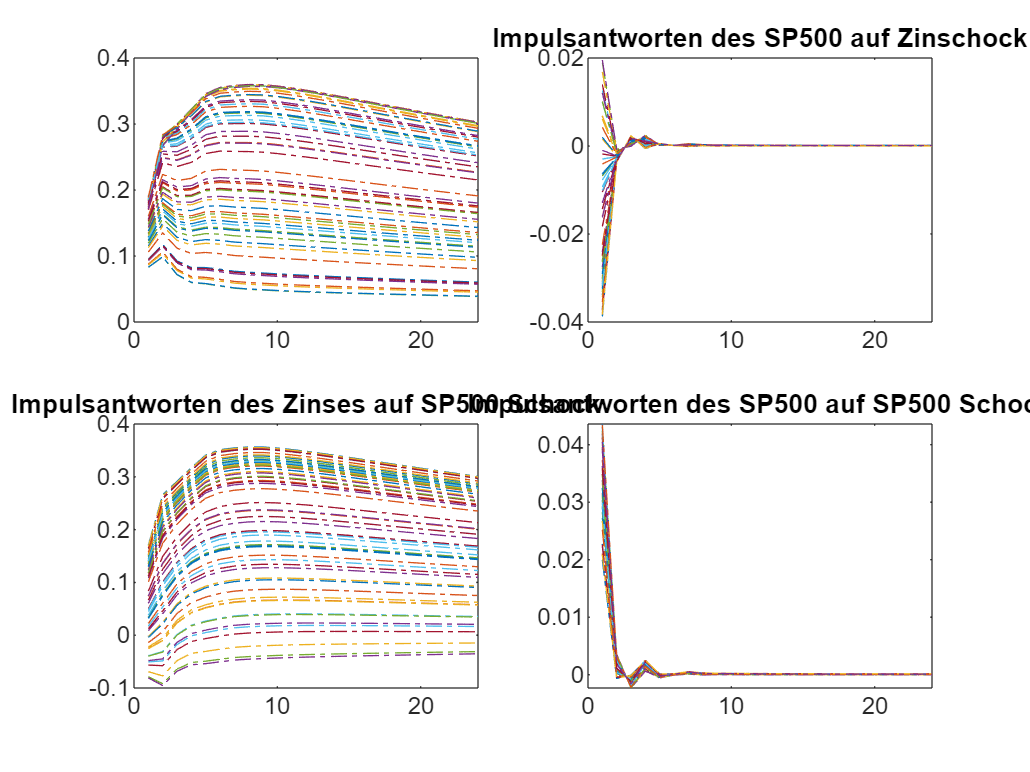



select = zeros(100,1);
for i = 1:100
    O = O_all(:,:,i) ;
    B = Bchol*O;
    e = inv(B)*u';e=e';


    rest1 = e(date_p == 2008 + (10-1)/12,2)< 0 ; % negative non-monetary policy shock in September 2008
    rest2 = abs(e(date_p == 2008 + (10-1)/12,1))< abs(e(date_p == 2008 + (10-1)/12,2)); % mp shock smaller than non-mp shock

    if rest1 & rest2
        select(i) = 1;
    end
end

figure
subplot(2,2,1)
plot(psi_ResponseI_SchockI(:,select==1),LineStyle="-.")    
subplot(2,2,2)
plot(psi_ResponseSP500_ShockI(:,select==1),LineStyle="-.")   
title("Impulsantworten des SP500 auf Zinschock")
subplot(2,2,3)
plot(psi_ResponseI_SchockSP500(:,select==1),LineStyle="-.")    
title("Impulsantworten des Zinses auf SP500 Schock")
subplot(2,2,4)
plot(psi_ResponseSP500_ShockSP500(:,select==1),LineStyle="-.")   
title("Impulsantworten des SP500 auf SP500 Schock") 

Langfristrestriktion: Restringiere die langfristige kumulierte Impulsantwort des SP500 auf Null (hier so nahe an Null wie unter den 100 möglichen Antworten nur möglich).


kumulierteAntwort = NaN(100,1);
for i = 1:100
    kumulierteAntwort(i) = sum(psi_ResponseSP500_ShockI(:,i));
end 
% Find index of the smallest squared value
[~, idx_min] = min(kumulierteAntwort.^2);
kumulierteAntwort(idx_min)

ans = 1.2266e-04

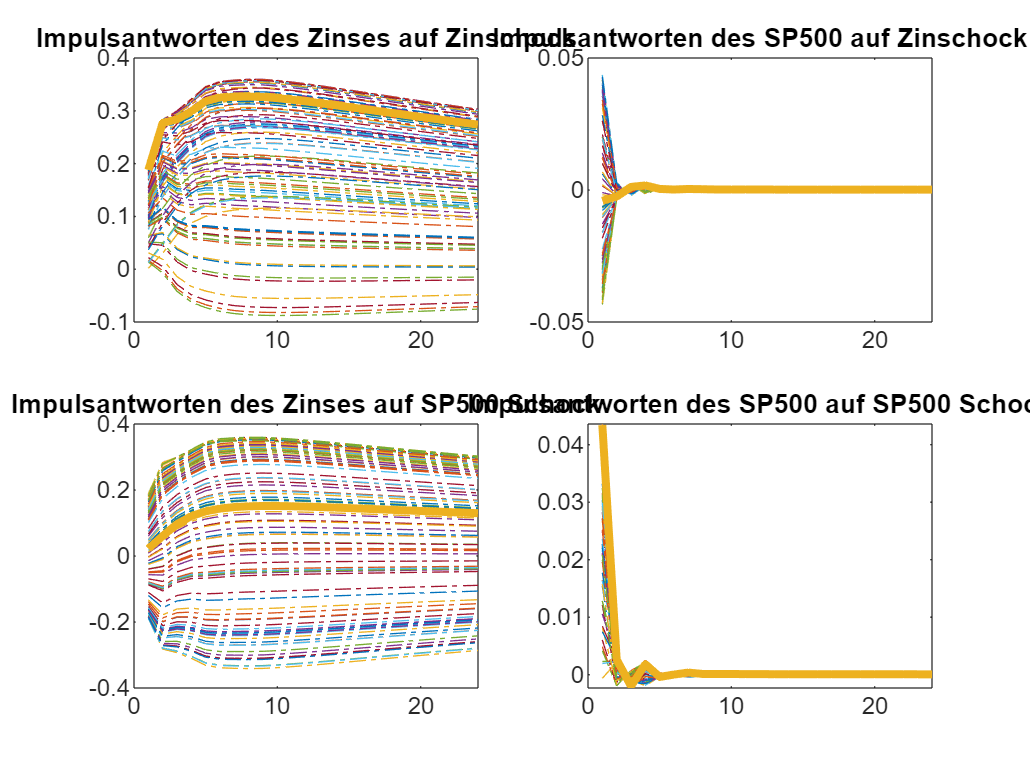


figure
subplot(2,2,1)
plot(psi_ResponseI_SchockI,LineStyle="-." )   
hold on
plot(psi_ResponseI_SchockI(:,idx_min), LineWidth=3)  
title("Impulsantworten des Zinses auf Zinschock")
subplot(2,2,2)
plot(psi_ResponseSP500_ShockI,LineStyle="-.")  
hold on
plot(psi_ResponseSP500_ShockI(:,idx_min), LineWidth=3)  
title("Impulsantworten des SP500 auf Zinschock")
subplot(2,2,3)
plot(psi_ResponseI_SchockSP500,LineStyle="-.")   
hold on
plot(psi_ResponseI_SchockSP500(:,idx_min), LineWidth=3)  
title("Impulsantworten des Zinses auf SP500 Schock")
subplot(2,2,4)
plot(psi_ResponseSP500_ShockSP500,LineStyle="-.")  
hold on
plot(psi_ResponseSP500_ShockSP500(:,idx_min), LineWidth=3)  
title("Impulsantworten des SP500 auf SP500 Schock") 

Proxy: Restringiert korrelation von SP500 Schock und dem Proxy für den geldpolitischen Schock auf Null (hier so nahe an Null wie unter den 100 möglichen Antworten nur möglich).

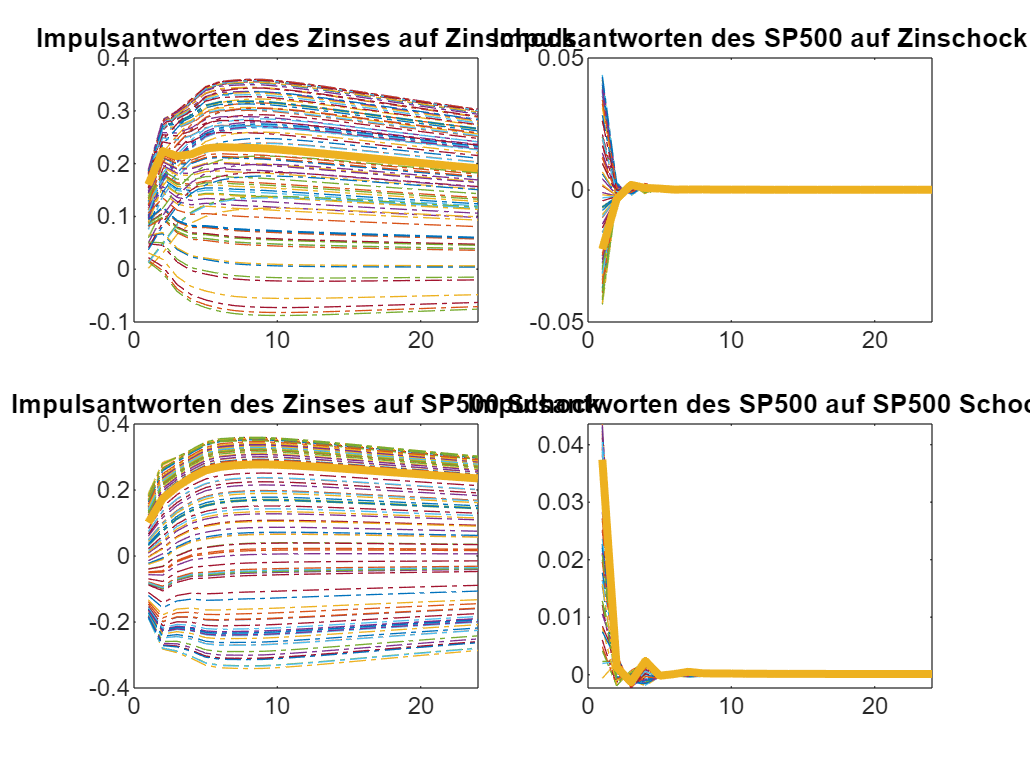

% Lade high-frequency Daten
hfdata = load("hfdata.mat");
year_hf = hfdata.hfproxy(2:end,1);
month_hf = hfdata.hfproxy(2:end,2);  
proxy	= hfdata.hfproxy(2:end,3); 

Korrelation_NonTarget_And_Proxy = NaN(100,1);
for i = 1:100 
    e = inv(Bchol*O_all(:,:,i)) * u'; e=e';
    Korrelation_NonTarget_And_Proxy(i) = mean(e(end-length(proxy)+1:end,2).*proxy);
end
% Find index of the smallest squared value
[~, idx_min] = min(Korrelation_NonTarget_And_Proxy.^2);
Korrelation_NonTarget_And_Proxy(idx_min);


figure
subplot(2,2,1)
plot(psi_ResponseI_SchockI,LineStyle="-." )   
hold on
plot(psi_ResponseI_SchockI(:,idx_min), LineWidth=3)  
title("Impulsantworten des Zinses auf Zinschock")
subplot(2,2,2)
plot(psi_ResponseSP500_ShockI,LineStyle="-.")  
hold on
plot(psi_ResponseSP500_ShockI(:,idx_min), LineWidth=3)  
title("Impulsantworten des SP500 auf Zinschock")
subplot(2,2,3)
plot(psi_ResponseI_SchockSP500,LineStyle="-.")   
hold on
plot(psi_ResponseI_SchockSP500(:,idx_min), LineWidth=3)  
title("Impulsantworten des Zinses auf SP500 Schock")
subplot(2,2,4)
plot(psi_ResponseSP500_ShockSP500,LineStyle="-.")  
hold on
plot(psi_ResponseSP500_ShockSP500(:,idx_min), LineWidth=3)  
title("Impulsantworten des SP500 auf SP500 Schock") 

Max-Share Identification: Maximiert FEVD des Zinsschocks für den Zins (nicht in Vorlesung behandelt)

share = NaN(100,1); 
select = zeros(100,1);
for i = 1:100
    share(i) = sum(psi_ResponseI_SchockI(:,i).^2) / (sum(psi_ResponseI_SchockI(:,i).^2) + sum(psi_ResponseI_SchockSP500(:,i).^2) ) ;
    if share(i)>0.75
        select(i) = 1; % Zinsschock erklärt mehr als 75% der Zinsvariation
    end
end 

% Find index of the smallest squared value
[~, idx_max] = max(share);
share(idx_max)

ans = 0.9968

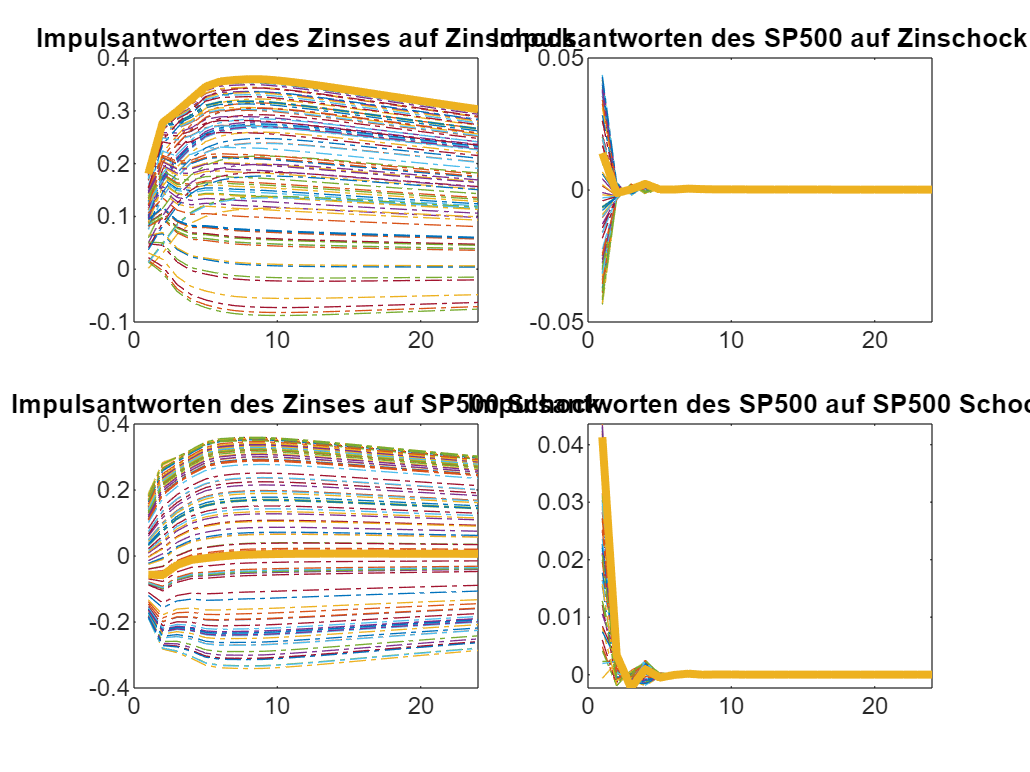


figure
subplot(2,2,1)
plot(psi_ResponseI_SchockI,LineStyle="-." )   
hold on
plot(psi_ResponseI_SchockI(:,idx_max), LineWidth=3)  
title("Impulsantworten des Zinses auf Zinschock")
subplot(2,2,2)
plot(psi_ResponseSP500_ShockI,LineStyle="-.")  
hold on
plot(psi_ResponseSP500_ShockI(:,idx_max), LineWidth=3)  
title("Impulsantworten des SP500 auf Zinschock")
subplot(2,2,3)
plot(psi_ResponseI_SchockSP500,LineStyle="-.")   
hold on
plot(psi_ResponseI_SchockSP500(:,idx_max), LineWidth=3)  
title("Impulsantworten des Zinses auf SP500 Schock")
subplot(2,2,4)
plot(psi_ResponseSP500_ShockSP500,LineStyle="-.")  
hold on
plot(psi_ResponseSP500_ShockSP500(:,idx_max), LineWidth=3)  
title("Impulsantworten des SP500 auf SP500 Schock") 

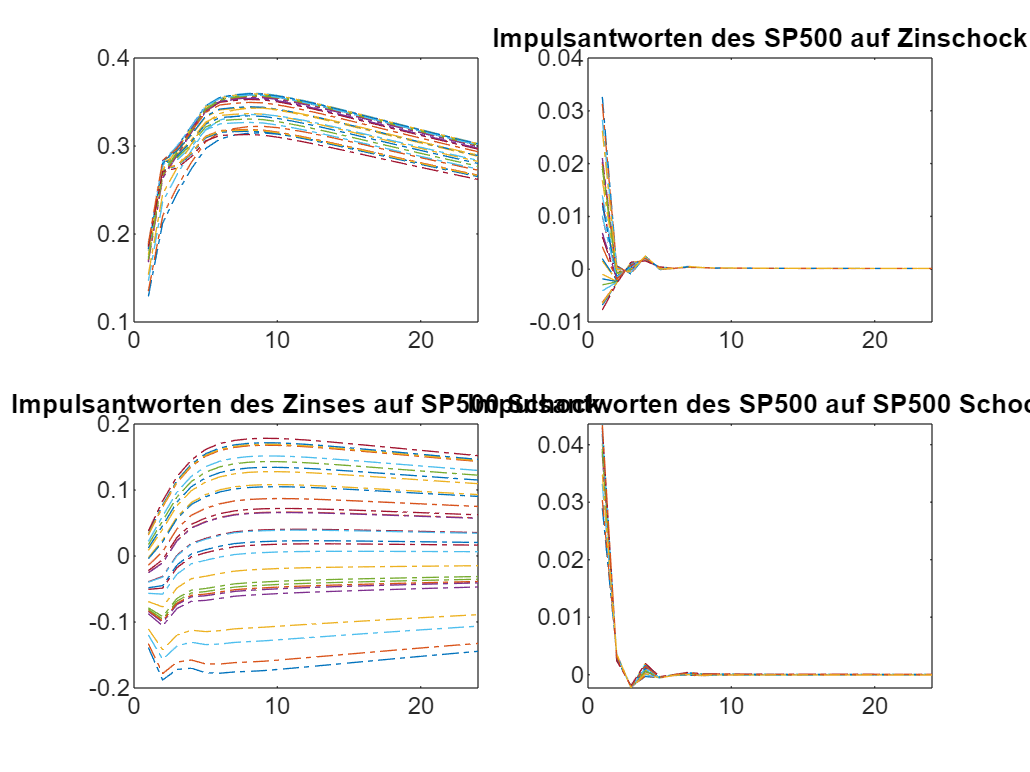


figure
subplot(2,2,1)
plot(psi_ResponseI_SchockI(:,select==1),LineStyle="-.")    
subplot(2,2,2)
plot(psi_ResponseSP500_ShockI(:,select==1),LineStyle="-.")   
title("Impulsantworten des SP500 auf Zinschock")
subplot(2,2,3)
plot(psi_ResponseI_SchockSP500(:,select==1),LineStyle="-.")    
title("Impulsantworten des Zinses auf SP500 Schock")
subplot(2,2,4)
plot(psi_ResponseSP500_ShockSP500(:,select==1),LineStyle="-.")   
title("Impulsantworten des SP500 auf SP500 Schock") 

Unabhängige Schocks: Schocks sollen unabhängig und nicht nur unkorrerliert sein.

independence = zeros(100,1);
for i=1: 100
    e = inv(Bchol*O_all(:,:,i)) * u'; e=e';
    independence(i) = mean(e(:,1).^2 .* e(:,2))^2 + mean(e(:,1) .* e(:,2).^2)^2;
end
% Find index of the smallest squared value
[~, idx_min] = min(independence.^2);
independence(idx_min)

ans = 7.0719e-05

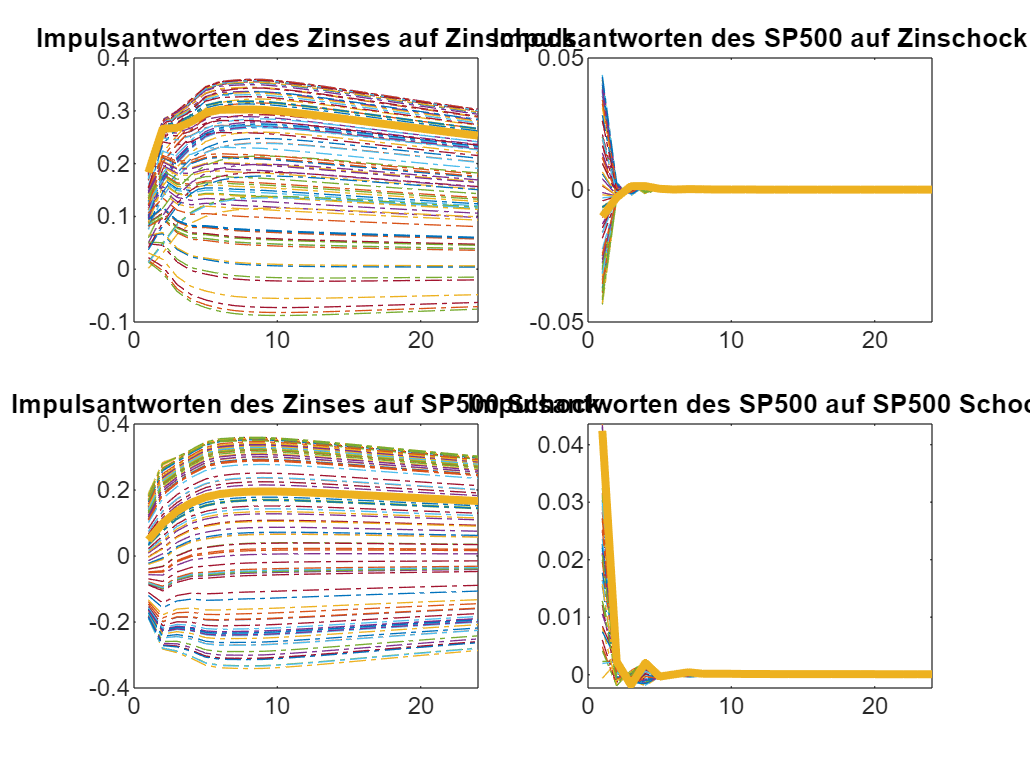



figure
subplot(2,2,1)
plot(psi_ResponseI_SchockI,LineStyle="-." )   
hold on
plot(psi_ResponseI_SchockI(:,idx_min), LineWidth=3)  
title("Impulsantworten des Zinses auf Zinschock")
subplot(2,2,2)
plot(psi_ResponseSP500_ShockI,LineStyle="-.")  
hold on
plot(psi_ResponseSP500_ShockI(:,idx_min), LineWidth=3)  
title("Impulsantworten des SP500 auf Zinschock")
subplot(2,2,3)
plot(psi_ResponseI_SchockSP500,LineStyle="-.")   
hold on
plot(psi_ResponseI_SchockSP500(:,idx_min), LineWidth=3)  
title("Impulsantworten des Zinses auf SP500 Schock")
subplot(2,2,4)
plot(psi_ResponseSP500_ShockSP500,LineStyle="-.")  
hold on
plot(psi_ResponseSP500_ShockSP500(:,idx_min), LineWidth=3)  
title("Impulsantworten des SP500 auf SP500 Schock") 

Heteroskedastizität: Angenommen die Varianz der strukturellen Schocks ändert sich in der Mitte des Samples. ...

state = ones(length(e),1); 
state(1:length(e)/2,1) = 0;

Korrelation_In_Different_States = NaN(100,1);
for i=1: 100
    e = inv(Bchol*O_all(:,:,i)) * u'; e=e'; 
    Korrelation_In_Different_States(i) = mean(e(state==0,1)  .* e(state==0,2))^2 + mean(e(state==1,1) .* e(state==1,2) )^2;
end
% Find index of the smallest squared value
[~, idx_min] = min(Korrelation_In_Different_States.^2);
Korrelation_In_Different_States(idx_min)

ans = 1.8873e-04

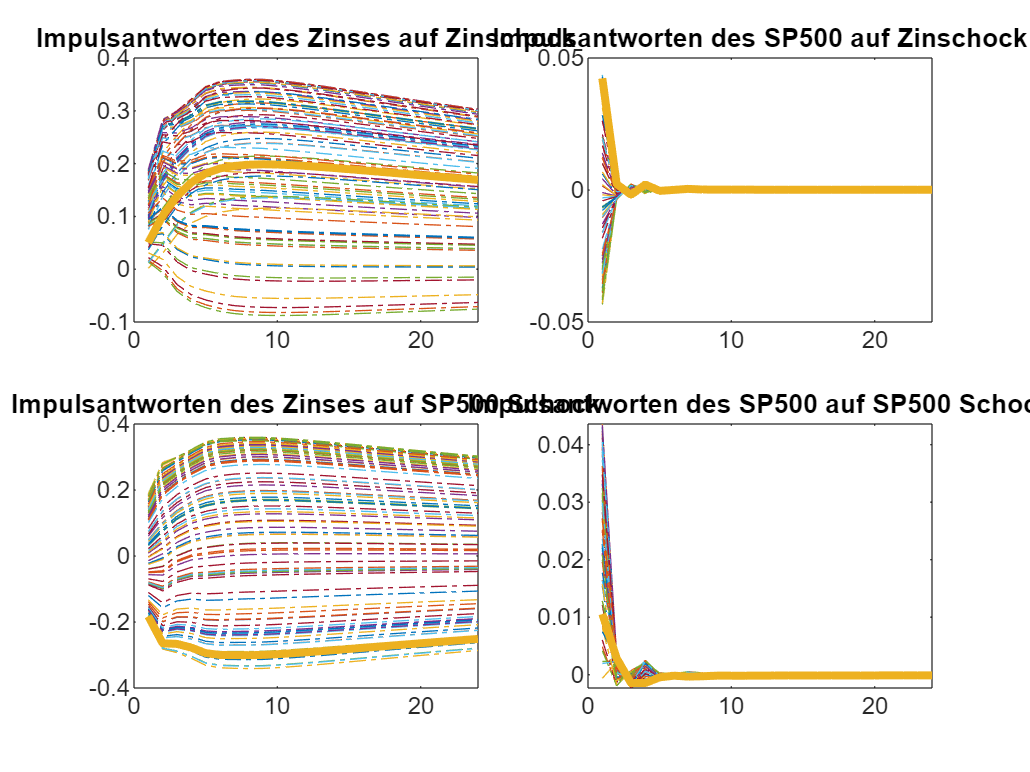



figure
subplot(2,2,1)
plot(psi_ResponseI_SchockI,LineStyle="-." )   
hold on
plot(psi_ResponseI_SchockI(:,idx_min), LineWidth=3)  
title("Impulsantworten des Zinses auf Zinschock")
subplot(2,2,2)
plot(psi_ResponseSP500_ShockI,LineStyle="-.")  
hold on
plot(psi_ResponseSP500_ShockI(:,idx_min), LineWidth=3)  
title("Impulsantworten des SP500 auf Zinschock")
subplot(2,2,3)
plot(psi_ResponseI_SchockSP500,LineStyle="-.")   
hold on
plot(psi_ResponseI_SchockSP500(:,idx_min), LineWidth=3)  
title("Impulsantworten des Zinses auf SP500 Schock")
subplot(2,2,4)
plot(psi_ResponseSP500_ShockSP500,LineStyle="-.")  
hold on
plot(psi_ResponseSP500_ShockSP500(:,idx_min), LineWidth=3)  
title("Impulsantworten des SP500 auf SP500 Schock") 